Tabla de valores

E=[-1, -4, -9, -16, -25, -36; % Partícula Independiente
    -0.49, -2.89, -7.29, -13.69, -22.09, -32.49; % Particula independiente + Apantallamiento
    -0.375, -2.75, -7.125, -13.5, -21.88, -32.25; % Método Perturbativo
    -0.473, -2.848, -7.222, -13.6, -21.97, -32.35; % Método Variacional
    -0.528, -2.904, -7.29, -13.66, -22.03, -32.42]; % Valores Exactos

Vamos a crear el espectro de energías

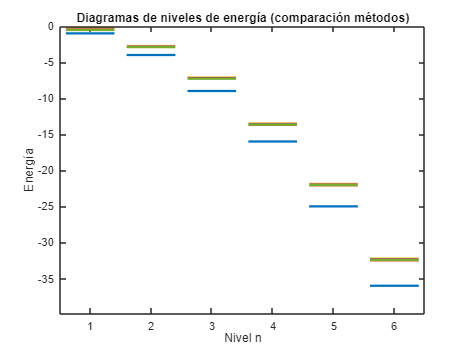

[nMet, nLev] = size(E);
colors = lines(nMet);

figure; hold on; box on

xWidth = 0.4;   % ancho fijo de cada línea

for k = 1:nLev
    for m = 1:nMet
        x = [k-xWidth, k+xWidth];    % mismo ancho para todas
        y = [E(m,k), E(m,k)];
        plot(x, y, 'LineWidth', 2, 'Color', colors(m,:));
    end
end

xlabel('Nivel n')
ylabel('Energía')
title('Diagramas de niveles de energía (comparación métodos)')

set(gca,'YDir','normal')   % o 'reverse' si quieres energías más negativas abajo
xlim([0.5 nLev+0.5])
%legend(metodos, 'Location','best')
set(gca,'YDir','normal')  % o 'reverse' si prefieres energías más negativas abajo

xlim([0.52 6.50])
ylim([-39.8 -0.0])